# **Solution multidomain exercise from 09-07-2025**

clear; clc; close all;

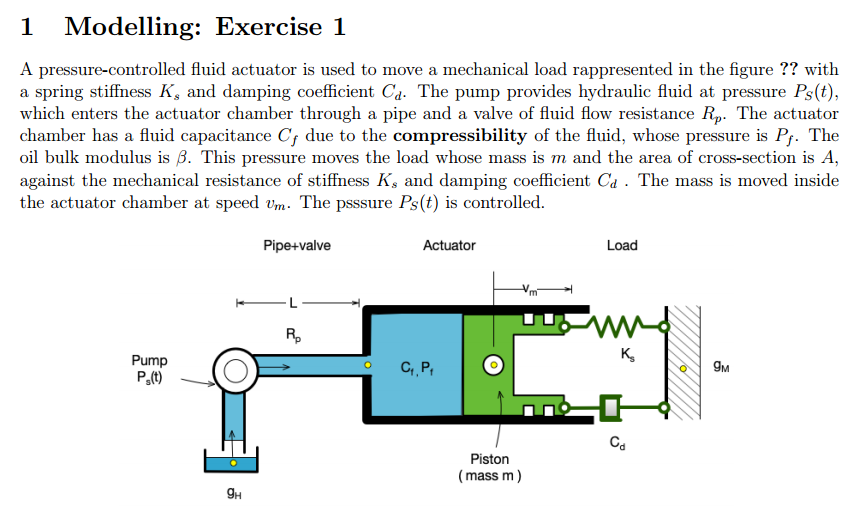

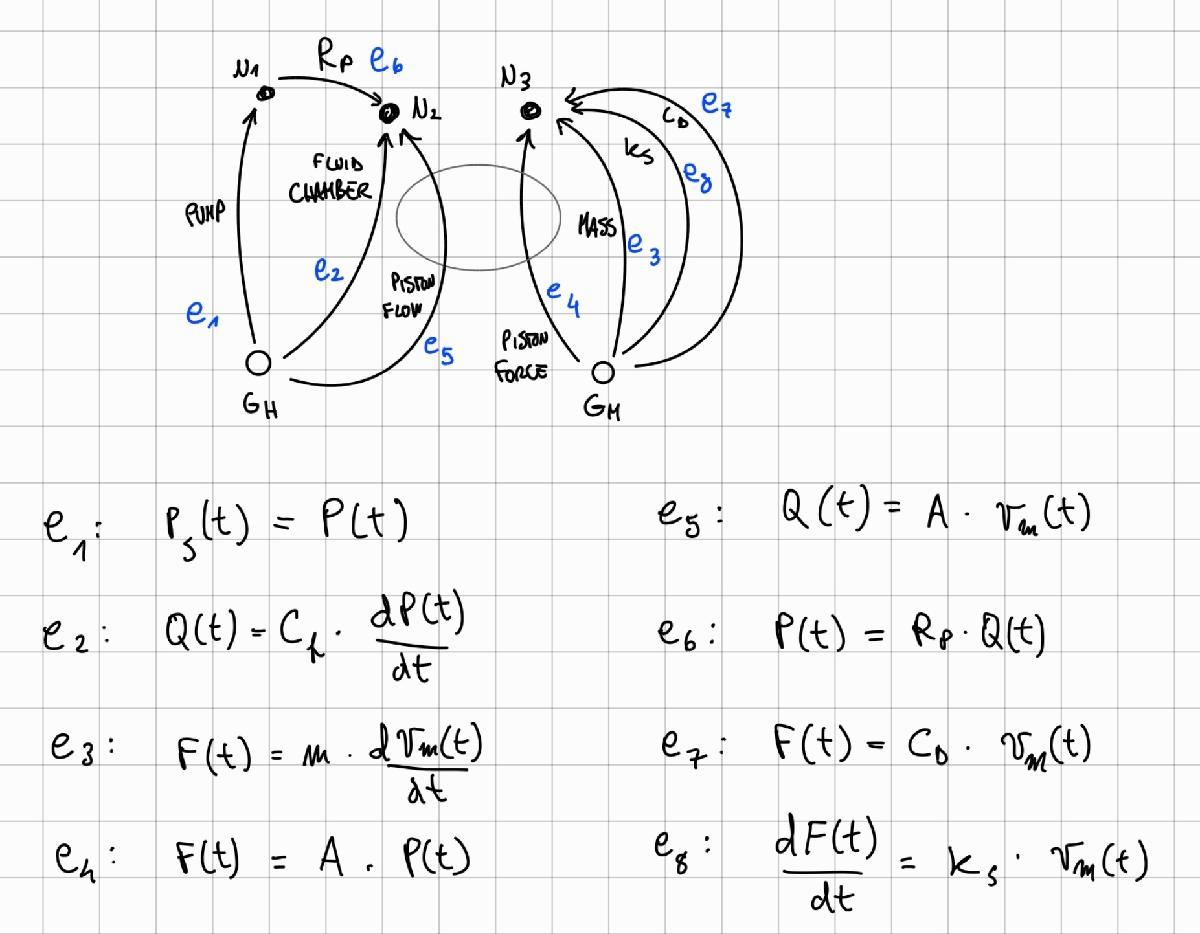

### System variables definition

syms t
addpath("MBLibs\")

% Through variables
syms Q_s(t) Q_c(t) F_m(t) F_p(t) Q_p(t) Q_r(t) F_d(t) F_k(t) 
tau_vars = [Q_s(t) Q_c(t) F_m(t) F_p(t) Q_p(t) Q_r(t) F_d(t) F_k(t)].'

$$tau\_vars = \left(\begin{array}{c} Q_{s}\left(t\right)\\ Q_{c}\left(t\right)\\ F_{m}\left(t\right)\\ F_{p}\left(t\right)\\ Q_{p}\left(t\right)\\ Q_{r}\left(t\right)\\ F_{d}\left(t\right)\\ F_{k}\left(t\right) \end{array}\right)$$

% Across variables
syms P_s(t) P_c(t) v_m(t) P_p(t) v_p(t) P_r(t) v_d(t) v_k(t)
alpha_vars = [P_s(t) P_c(t) v_m(t) P_p(t) v_p(t) P_r(t) v_d(t) v_k(t)].'

$$alpha\_vars = \left(\begin{array}{c} P_{s}\left(t\right)\\ P_{c}\left(t\right)\\ v_{m}\left(t\right)\\ P_{p}\left(t\right)\\ v_{p}\left(t\right)\\ P_{r}\left(t\right)\\ v_{d}\left(t\right)\\ v_{k}\left(t\right) \end{array}\right)$$

#### Constitutive equations

% System parameters
syms PS(t) C_f m A R_p C_d K_s

const_eq = [
    P_s(t) == PS(t);
    diff(P_c(t),t) == 1/C_f * Q_c(t);
    diff(v_m(t),t) == 1/m * F_m(t);
    A * P_p(t) == F_p(t);
    Q_p(t) == A * v_p(t);
    P_r(t) == R_p * Q_r(t);
    F_d(t) == C_d * v_d(t);
    diff(F_k(t),t) == K_s * v_k(t)
]

$$const\_eq = \left(\begin{array}{c} P_{s}\left(t\right)=\mathrm{PS}\left(t\right)\\ \frac{\partial }{\partial t}P_{c}\left(t\right)=\frac{Q_{c}\left(t\right)}{C_{f}}\\ \frac{\partial }{\partial t}v_{m}\left(t\right)=\frac{F_{m}\left(t\right)}{m}\\ A\,P_{p}\left(t\right)=F_{p}\left(t\right)\\ Q_{p}\left(t\right)=A\,v_{p}\left(t\right)\\ P_{r}\left(t\right)=R_{p}\,Q_{r}\left(t\right)\\ F_{d}\left(t\right)=C_{d}\,v_{d}\left(t\right)\\ \frac{\partial }{\partial t}F_{k}\left(t\right)=K_{s}\,v_{k}\left(t\right) \end{array}\right)$$

### Incidence matrix and dimensions

IM = [
    1   0   0   0   0   -1  0   0;
    0   1   0   0   1   1   0   0;
    0   0   1   1   0   0   1   1;
    -1  -1  0   0   -1  0   0   0;
    0   0   -1  -1  0   0   -1  -1
]

IM =      1     0     0     0     0    -1     0     0
     0     1     0     0     1     1     0     0
     0     0     1     1     0     0     1     1
    -1    -1     0     0    -1     0     0     0
     0     0    -1    -1     0     0    -1    -1



[nn, ne] = size(IM)

nn = 5

ne = 8


nb = rank(IM)

nb = 3

nc = ne - nb

nc = 5

### A matrix and node equations

A = sym(IM(1:nb, 1:ne))

$$A = \left(\begin{array}{cccccccc} 1 & 0 & 0 & 0 & 0 & -1 & 0 & 0\\ 0 & 1 & 0 & 0 & 1 & 1 & 0 & 0\\ 0 & 0 & 1 & 1 & 0 & 0 & 1 & 1 \end{array}\right)$$

Af = rref(A)

$$Af = \left(\begin{array}{cccccccc} 1 & 0 & 0 & 0 & 0 & -1 & 0 & 0\\ 0 & 1 & 0 & 0 & 1 & 1 & 0 & 0\\ 0 & 0 & 1 & 1 & 0 & 0 & 1 & 1 \end{array}\right)$$

Ac = Af(:, nb+1:end)

$$Ac = \left(\begin{array}{ccccc} 0 & 0 & -1 & 0 & 0\\ 0 & 1 & 1 & 0 & 0\\ 1 & 0 & 0 & 1 & 1 \end{array}\right)$$

**Node equations**

node_eqns = tau_vars(1:nb) == -Ac*tau_vars(nb+1:end)

$$node\_eqns = \left(\begin{array}{c} Q_{s}\left(t\right)=Q_{r}\left(t\right)\\ Q_{c}\left(t\right)=-Q_{p}\left(t\right)-Q_{r}\left(t\right)\\ F_{m}\left(t\right)=-F_{d}\left(t\right)-F_{k}\left(t\right)-F_{p}\left(t\right) \end{array}\right)$$

### B matrix and loop equations

Bf = null(Af).'

$$Bf = \left(\begin{array}{cccccccc} 0 & 0 & -1 & 1 & 0 & 0 & 0 & 0\\ 0 & -1 & 0 & 0 & 1 & 0 & 0 & 0\\ 1 & -1 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & -1 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & -1 & 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

Bb = -Ac'

$$Bb = \left(\begin{array}{ccc} 0 & 0 & -1\\ 0 & -1 & 0\\ 1 & -1 & 0\\ 0 & 0 & -1\\ 0 & 0 & -1 \end{array}\right)$$

**Loop equations**

loop_eqns = alpha_vars(nb+1:end) == -Bb*alpha_vars(1:nb)

$$loop\_eqns = \left(\begin{array}{c} P_{p}\left(t\right)=v_{m}\left(t\right)\\ v_{p}\left(t\right)=P_{c}\left(t\right)\\ P_{r}\left(t\right)=P_{c}\left(t\right)-P_{s}\left(t\right)\\ v_{d}\left(t\right)=v_{m}\left(t\right)\\ v_{k}\left(t\right)=v_{m}\left(t\right) \end{array}\right)$$

### DAE system construction

% Dependent variables
qvars_d = [lhs(node_eqns); lhs(loop_eqns)];
% Independent (DAE) vars
allvars = [tau_vars; alpha_vars];
DAE_vars = setdiff(allvars, qvars_d)

$$DAE\_vars = \left(\begin{array}{c} F_{d}\left(t\right)\\ F_{k}\left(t\right)\\ F_{p}\left(t\right)\\ P_{c}\left(t\right)\\ P_{s}\left(t\right)\\ Q_{p}\left(t\right)\\ Q_{r}\left(t\right)\\ v_{m}\left(t\right) \end{array}\right)$$

Assembling the system

tmp = subs(const_eq, lhs(loop_eqns), rhs(loop_eqns));
DAE_eqns = subs(tmp, lhs(node_eqns), rhs(node_eqns))

$$DAE\_eqns = \left(\begin{array}{c} P_{s}\left(t\right)=\mathrm{PS}\left(t\right)\\ \frac{\partial }{\partial t}P_{c}\left(t\right)=-\frac{Q_{p}\left(t\right)+Q_{r}\left(t\right)}{C_{f}}\\ \frac{\partial }{\partial t}v_{m}\left(t\right)=-\frac{F_{d}\left(t\right)+F_{k}\left(t\right)+F_{p}\left(t\right)}{m}\\ A\,v_{m}\left(t\right)=F_{p}\left(t\right)\\ Q_{p}\left(t\right)=A\,P_{c}\left(t\right)\\ P_{c}\left(t\right)-P_{s}\left(t\right)=R_{p}\,Q_{r}\left(t\right)\\ F_{d}\left(t\right)=C_{d}\,v_{m}\left(t\right)\\ \frac{\partial }{\partial t}F_{k}\left(t\right)=K_{s}\,v_{m}\left(t\right) \end{array}\right)$$

Mass matrix form and reorder

[E, G] = massMatrixForm(DAE_eqns, DAE_vars)

$$E = \left(\begin{array}{cccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

$$G = \left(\begin{array}{c} \mathrm{PS}\left(t\right)-P_{s}\left(t\right)\\ -\frac{Q_{p}\left(t\right)+Q_{r}\left(t\right)}{C_{f}}\\ -\frac{F_{d}\left(t\right)+F_{k}\left(t\right)+F_{p}\left(t\right)}{m}\\ F_{p}\left(t\right)-A\,v_{m}\left(t\right)\\ A\,P_{c}\left(t\right)-Q_{p}\left(t\right)\\ P_{s}\left(t\right)-P_{c}\left(t\right)+R_{p}\,Q_{r}\left(t\right)\\ C_{d}\,v_{m}\left(t\right)-F_{d}\left(t\right)\\ K_{s}\,v_{m}\left(t\right) \end{array}\right)$$

[p,q,~,~,~,~] = dmperm(double(E));
E_sort = E(p,:)

$$E\_sort = \left(\begin{array}{cccccccc} 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

G_sort = G(p)

$$G\_sort = \left(\begin{array}{c} K_{s}\,v_{m}\left(t\right)\\ -\frac{Q_{p}\left(t\right)+Q_{r}\left(t\right)}{C_{f}}\\ -\frac{F_{d}\left(t\right)+F_{k}\left(t\right)+F_{p}\left(t\right)}{m}\\ \mathrm{PS}\left(t\right)-P_{s}\left(t\right)\\ F_{p}\left(t\right)-A\,v_{m}\left(t\right)\\ A\,P_{c}\left(t\right)-Q_{p}\left(t\right)\\ P_{s}\left(t\right)-P_{c}\left(t\right)+R_{p}\,Q_{r}\left(t\right)\\ C_{d}\,v_{m}\left(t\right)-F_{d}\left(t\right) \end{array}\right)$$

#### Check if the system is index 1

inv0 = G_sort(4:end);
inv0_diff = diff(inv0,t)

$$inv0\_diff = \left(\begin{array}{c} \frac{\partial }{\partial t}\mathrm{PS}\left(t\right)-\frac{\partial }{\partial t}P_{s}\left(t\right)\\ \frac{\partial }{\partial t}F_{p}\left(t\right)-A\,\frac{\partial }{\partial t}v_{m}\left(t\right)\\ A\,\frac{\partial }{\partial t}P_{c}\left(t\right)-\frac{\partial }{\partial t}Q_{p}\left(t\right)\\ R_{p}\,\frac{\partial }{\partial t}Q_{r}\left(t\right)-\frac{\partial }{\partial t}P_{c}\left(t\right)+\frac{\partial }{\partial t}P_{s}\left(t\right)\\ C_{d}\,\frac{\partial }{\partial t}v_{m}\left(t\right)-\frac{\partial }{\partial t}F_{d}\left(t\right) \end{array}\right)$$

DAE_eq_tmp = E_sort*diff(DAE_vars,t)-[G_sort(1:3);inv0_diff]

$$DAE\_eq\_tmp = \left(\begin{array}{c} \frac{\partial }{\partial t}F_{k}\left(t\right)-K_{s}\,v_{m}\left(t\right)\\ \frac{\partial }{\partial t}P_{c}\left(t\right)+\frac{Q_{p}\left(t\right)+Q_{r}\left(t\right)}{C_{f}}\\ \frac{F_{d}\left(t\right)+F_{k}\left(t\right)+F_{p}\left(t\right)}{m}+\frac{\partial }{\partial t}v_{m}\left(t\right)\\ \frac{\partial }{\partial t}P_{s}\left(t\right)-\frac{\partial }{\partial t}\mathrm{PS}\left(t\right)\\ A\,\frac{\partial }{\partial t}v_{m}\left(t\right)-\frac{\partial }{\partial t}F_{p}\left(t\right)\\ \frac{\partial }{\partial t}Q_{p}\left(t\right)-A\,\frac{\partial }{\partial t}P_{c}\left(t\right)\\ \frac{\partial }{\partial t}P_{c}\left(t\right)-R_{p}\,\frac{\partial }{\partial t}Q_{r}\left(t\right)-\frac{\partial }{\partial t}P_{s}\left(t\right)\\ \frac{\partial }{\partial t}F_{d}\left(t\right)-C_{d}\,\frac{\partial }{\partial t}v_{m}\left(t\right) \end{array}\right)$$

[E0, G0] = massMatrixForm(DAE_eq_tmp, DAE_vars)

$$E0 = \left(\begin{array}{cccccccc} 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & -1 & 0 & 0 & 0 & 0 & A\\ 0 & 0 & 0 & -A & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 & -1 & 0 & -R_{p} & 0\\ 1 & 0 & 0 & 0 & 0 & 0 & 0 & -C_{d} \end{array}\right)$$

$$G0 = \left(\begin{array}{c} K_{s}\,v_{m}\left(t\right)\\ -\frac{Q_{p}\left(t\right)+Q_{r}\left(t\right)}{C_{f}}\\ -\frac{F_{d}\left(t\right)+F_{k}\left(t\right)+F_{p}\left(t\right)}{m}\\ \frac{\partial }{\partial t}\mathrm{PS}\left(t\right)\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$

if(rank(E0) == length(DAE_vars))
    disp("System is index-1")
end

System is index-1


#### Final DAE system

DAE_eqns = E_sort*diff(DAE_vars,t) - G_sort == 0

$$DAE\_eqns = \left(\begin{array}{c} \frac{\partial }{\partial t}F_{k}\left(t\right)-K_{s}\,v_{m}\left(t\right)=0\\ \frac{\partial }{\partial t}P_{c}\left(t\right)+\frac{Q_{p}\left(t\right)+Q_{r}\left(t\right)}{C_{f}}=0\\ \frac{F_{d}\left(t\right)+F_{k}\left(t\right)+F_{p}\left(t\right)}{m}+\frac{\partial }{\partial t}v_{m}\left(t\right)=0\\ P_{s}\left(t\right)-\mathrm{PS}\left(t\right)=0\\ A\,v_{m}\left(t\right)-F_{p}\left(t\right)=0\\ Q_{p}\left(t\right)-A\,P_{c}\left(t\right)=0\\ P_{c}\left(t\right)-P_{s}\left(t\right)-R_{p}\,Q_{r}\left(t\right)=0\\ F_{d}\left(t\right)-C_{d}\,v_{m}\left(t\right)=0 \end{array}\right)$$

Differential and algebraic equations (with respective variables)

ODE_eqns = DAE_eqns(1:3)

$$ODE\_eqns = \left(\begin{array}{c} \frac{\partial }{\partial t}F_{k}\left(t\right)-K_{s}\,v_{m}\left(t\right)=0\\ \frac{\partial }{\partial t}P_{c}\left(t\right)+\frac{Q_{p}\left(t\right)+Q_{r}\left(t\right)}{C_{f}}=0\\ \frac{F_{d}\left(t\right)+F_{k}\left(t\right)+F_{p}\left(t\right)}{m}+\frac{\partial }{\partial t}v_{m}\left(t\right)=0 \end{array}\right)$$

ODE_vars = get_ode_vars(DAE_vars, ODE_eqns)

$$ODE\_vars = \left(\begin{array}{c} F_{k}\left(t\right)\\ P_{c}\left(t\right)\\ v_{m}\left(t\right) \end{array}\right)$$

alg_eqns = DAE_eqns(4:end)

$$alg\_eqns = \left(\begin{array}{c} P_{s}\left(t\right)-\mathrm{PS}\left(t\right)=0\\ A\,v_{m}\left(t\right)-F_{p}\left(t\right)=0\\ Q_{p}\left(t\right)-A\,P_{c}\left(t\right)=0\\ P_{c}\left(t\right)-P_{s}\left(t\right)-R_{p}\,Q_{r}\left(t\right)=0\\ F_{d}\left(t\right)-C_{d}\,v_{m}\left(t\right)=0 \end{array}\right)$$

alg_vars = setdiff(DAE_vars, ODE_vars)

$$alg\_vars = \left(\begin{array}{c} F_{d}\left(t\right)\\ F_{p}\left(t\right)\\ P_{s}\left(t\right)\\ Q_{p}\left(t\right)\\ Q_{r}\left(t\right) \end{array}\right)$$